% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

## Reading in data from day 3

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-07-24/";

% well 1 data

file_name = "Blood_Plasma1(40x,495mW,Well1)_2000_30_2024-07-24-14.57.44.427.csv";
file_path = data_path+file_name;
blood_1_1_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well1)_2000_30_2024-07-24-14.59.32.280.csv";
file_path = strcat(data_path,file_name);
blood_2_1_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well1)_2000_30_2024-07-24-15.01.04.670.csv";
file_path = strcat(data_path,file_name);
blood_3_1_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well1)_2000_30_2024-07-24-15.02.42.453.csv";
file_path = strcat(data_path,file_name);
blood_4_1_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well1)_2000_30_2024-07-24-15.04.13.603.csv";
file_path = strcat(data_path,file_name);
blood_5_1_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well1)_2000_30_2024-07-24-15.05.55.007.csv";
file_path = strcat(data_path,file_name);
blood_6_1_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well1)_2000_30_2024-07-24-15.07.25.433.csv";
file_path = strcat(data_path,file_name);
blood_7_1_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well1)_2000_30_2024-07-24-15.09.05.273.csv";
file_path = strcat(data_path,file_name);
blood_8_1_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well1)_2000_30_2024-07-24-15.10.45.997.csv";
file_path = strcat(data_path,file_name);
blood_9_1_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well1)_2000_30_2024-07-24-15.12.23.980.csv";
file_path = strcat(data_path,file_name);
blood_10_1_3 = csvread(file_path, numMetadataRows, 0);

% well 2 data

file_name = "Blood_Plasma1(40x,495mW,Well2)_2000_30_2024-07-24-15.17.27.560.csv";
file_path = data_path+file_name;
blood_1_2_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well2)_2000_30_2024-07-24-15.19.03.810.csv";
file_path = strcat(data_path,file_name);
blood_2_2_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well2)_2000_30_2024-07-24-15.20.37.067.csv";
file_path = strcat(data_path,file_name);
blood_3_2_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well2)_2000_30_2024-07-24-15.22.12.313.csv";
file_path = strcat(data_path,file_name);
blood_4_2_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well2)_2000_30_2024-07-24-15.23.43.430.csv";
file_path = strcat(data_path,file_name);
blood_5_2_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well2)_2000_30_2024-07-24-15.25.19.173.csv";
file_path = strcat(data_path,file_name);
blood_6_2_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well2)_2000_30_2024-07-24-15.26.53.797.csv";
file_path = strcat(data_path,file_name);
blood_7_2_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well2)_2000_30_2024-07-24-15.28.27.710.csv";
file_path = strcat(data_path,file_name);
blood_8_2_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well2)_2000_30_2024-07-24-15.30.01.193.csv";
file_path = strcat(data_path,file_name);
blood_9_2_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well2)_2000_30_2024-07-24-15.31.40.613.csv";
file_path = strcat(data_path,file_name);
blood_10_2_3 = csvread(file_path, numMetadataRows, 0);

% well 3 data

file_name = "Blood_Plasma1(40x,495mW,Well3)_2000_30_2024-07-24-15.35.48.637.csv";
file_path = data_path+file_name;
blood_1_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well3)_2000_30_2024-07-24-15.37.20.120.csv";
file_path = strcat(data_path,file_name);
blood_2_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well3)_2000_30_2024-07-24-15.38.49.877.csv";
file_path = strcat(data_path,file_name);
blood_3_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well3)_2000_30_2024-07-24-15.40.27.253.csv";
file_path = strcat(data_path,file_name);
blood_4_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well3)_2000_30_2024-07-24-15.42.05.273.csv";
file_path = strcat(data_path,file_name);
blood_5_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well3)_2000_30_2024-07-24-15.43.44.337.csv";
file_path = strcat(data_path,file_name);
blood_6_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well3)_2000_30_2024-07-24-15.45.16.387.csv";
file_path = strcat(data_path,file_name);
blood_7_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well3)_2000_30_2024-07-24-15.46.45.360.csv";
file_path = strcat(data_path,file_name);
blood_8_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well3)_2000_30_2024-07-24-15.48.17.017.csv";
file_path = strcat(data_path,file_name);
blood_9_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well3)_2000_30_2024-07-24-15.49.50.290.csv";
file_path = strcat(data_path,file_name);
blood_10_3_3 = csvread(file_path, numMetadataRows, 0);

file_name = "NIST(40x,495mW)_50_250_2024-07-24-14.03.28.047.csv";
file_path = strcat(data_path,file_name);

Unrecognized function or variable 'data_path'.

NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_250_2024-07-24-14.17.49.100.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_250_2024-07-24-14.22.13.103.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring Data from Day 3

wavenumber = blood_1_3_3(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;

wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];

blood_1_1_3(:, blood_1_1_3(1, :) <= t1) = [];
blood_1_1_3(:, blood_1_1_3(1, :) >= t2) = [];
blood_2_1_3(:, blood_2_1_3(1, :) <= t1) = [];
blood_2_1_3(:, blood_2_1_3(1, :) >= t2) = [];
blood_3_1_3(:, blood_3_1_3(1, :) <= t1) = [];
blood_3_1_3(:, blood_3_1_3(1, :) >= t2) = [];
blood_4_1_3(:, blood_4_1_3(1, :) <= t1) = [];
blood_4_1_3(:, blood_4_1_3(1, :) >= t2) = [];
blood_5_1_3(:, blood_5_1_3(1, :) <= t1) = [];
blood_5_1_3(:, blood_5_1_3(1, :) >= t2) = [];
blood_6_1_3(:, blood_6_1_3(1, :) <= t1) = [];
blood_6_1_3(:, blood_6_1_3(1, :) >= t2) = [];
blood_7_1_3(:, blood_7_1_3(1, :) <= t1) = [];
blood_7_1_3(:, blood_7_1_3(1, :) >= t2) = [];
blood_8_1_3(:, blood_8_1_3(1, :) <= t1) = [];
blood_8_1_3(:, blood_8_1_3(1, :) >= t2) = [];
blood_9_1_3(:, blood_9_1_3(1, :) <= t1) = [];
blood_9_1_3(:, blood_9_1_3(1, :) >= t2) = [];
blood_10_1_3(:, blood_10_1_3(1, :) <= t1) = [];
blood_10_1_3(:, blood_10_1_3(1, :) >= t2) = [];

blood_1_2_3(:, blood_1_2_3(1, :) <= t1) = [];
blood_1_2_3(:, blood_1_2_3(1, :) >= t2) = [];
blood_2_2_3(:, blood_2_2_3(1, :) <= t1) = [];
blood_2_2_3(:, blood_2_2_3(1, :) >= t2) = [];
blood_3_2_3(:, blood_3_2_3(1, :) <= t1) = [];
blood_3_2_3(:, blood_3_2_3(1, :) >= t2) = [];
blood_4_2_3(:, blood_4_2_3(1, :) <= t1) = [];
blood_4_2_3(:, blood_4_2_3(1, :) >= t2) = [];
blood_5_2_3(:, blood_5_2_3(1, :) <= t1) = [];
blood_5_2_3(:, blood_5_2_3(1, :) >= t2) = [];
blood_6_2_3(:, blood_6_2_3(1, :) <= t1) = [];
blood_6_2_3(:, blood_6_2_3(1, :) >= t2) = [];
blood_7_2_3(:, blood_7_2_3(1, :) <= t1) = [];
blood_7_2_3(:, blood_7_2_3(1, :) >= t2) = [];
blood_8_2_3(:, blood_8_2_3(1, :) <= t1) = [];
blood_8_2_3(:, blood_8_2_3(1, :) >= t2) = [];
blood_9_2_3(:, blood_9_2_3(1, :) <= t1) = [];
blood_9_2_3(:, blood_9_2_3(1, :) >= t2) = [];
blood_10_2_3(:, blood_10_2_3(1, :) <= t1) = [];
blood_10_2_3(:, blood_10_2_3(1, :) >= t2) = [];

blood_1_3_3(:, blood_1_3_3(1, :) <= t1) = [];
blood_1_3_3(:, blood_1_3_3(1, :) >= t2) = [];
blood_2_3_3(:, blood_2_3_3(1, :) <= t1) = [];
blood_2_3_3(:, blood_2_3_3(1, :) >= t2) = [];
blood_3_3_3(:, blood_3_3_3(1, :) <= t1) = [];
blood_3_3_3(:, blood_3_3_3(1, :) >= t2) = [];
blood_4_3_3(:, blood_4_3_3(1, :) <= t1) = [];
blood_4_3_3(:, blood_4_3_3(1, :) >= t2) = [];
blood_5_3_3(:, blood_5_3_3(1, :) <= t1) = [];
blood_5_3_3(:, blood_5_3_3(1, :) >= t2) = [];
blood_6_3_3(:, blood_6_3_3(1, :) <= t1) = [];
blood_6_3_3(:, blood_6_3_3(1, :) >= t2) = [];
blood_7_3_3(:, blood_7_3_3(1, :) <= t1) = [];
blood_7_3_3(:, blood_7_3_3(1, :) >= t2) = [];
blood_8_3_3(:, blood_8_3_3(1, :) <= t1) = [];
blood_8_3_3(:, blood_8_3_3(1, :) >= t2) = [];
blood_9_3_3(:, blood_9_3_3(1, :) <= t1) = [];
blood_9_3_3(:, blood_9_3_3(1, :) >= t2) = [];
blood_10_3_3(:, blood_10_3_3(1, :) <= t1) = [];
blood_10_3_3(:, blood_10_3_3(1, :) >= t2) = [];

shifts = wavenumber;

blood1_1_3 = blood_1_1_3(2:end, :);
blood2_1_3 = blood_2_1_3(2:end, :);
blood3_1_3 = blood_3_1_3(2:end, :);
blood4_1_3 = blood_4_1_3(2:end, :);
blood5_1_3 = blood_5_1_3(2:end, :);
blood6_1_3 = blood_6_1_3(2:end, :);
blood7_1_3 = blood_7_1_3(2:end, :);
blood8_1_3 = blood_8_1_3(2:end, :);
blood9_1_3 = blood_9_1_3(2:end, :);
blood10_1_3 = blood_10_1_3(2:end, :);

blood1_2_3 = blood_1_2_3(2:end, :);
blood2_2_3 = blood_2_2_3(2:end, :);
blood3_2_3 = blood_3_2_3(2:end, :);
blood4_2_3 = blood_4_2_3(2:end, :);
blood5_2_3 = blood_5_2_3(2:end, :);
blood6_2_3 = blood_6_2_3(2:end, :);
blood7_2_3 = blood_7_2_3(2:end, :);
blood8_2_3 = blood_8_2_3(2:end, :);
blood9_2_3 = blood_9_2_3(2:end, :);
blood10_2_3 = blood_10_2_3(2:end, :);

blood1_3_3 = blood_1_3_3(2:end, :);
blood2_3_3 = blood_2_3_3(2:end, :);
blood3_3_3 = blood_3_3_3(2:end, :);
blood4_3_3 = blood_4_3_3(2:end, :);
blood5_3_3 = blood_5_3_3(2:end, :);
blood6_3_3 = blood_6_3_3(2:end, :);
blood7_3_3 = blood_7_3_3(2:end, :);
blood8_3_3 = blood_8_3_3(2:end, :);
blood9_3_3 = blood_9_3_3(2:end, :);
blood10_3_3 = blood_10_3_3(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

## Preprocessing Data from Day 3

% Well 1

blood_1_3 = [blood1_1_3;blood2_1_3;blood3_1_3;blood4_1_3;blood5_1_3;blood6_1_3;blood7_1_3;blood8_1_3;blood9_1_3;blood10_1_3];
pro_blood_1_3 = apply(blood_1_3, [6,1,10,11,8,2,5,6,7]);

% Well 2

blood_2_3 = [blood1_2_3;blood2_2_3;blood3_2_3;blood4_2_3;blood5_2_3;blood6_2_3;blood7_2_3;blood8_2_3;blood9_2_3;blood10_2_3];
pro_blood_2_3 = apply(blood_2_3, [6,1,10,11,8,2,5,6,7]);

% Well 3

blood_3_3 = [blood1_3_3;blood2_3_3;blood3_3_3;blood4_3_3;blood5_3_3;blood6_3_3;blood7_3_3;blood8_3_3;blood9_3_3;blood10_3_3];
pro_blood_3_3 = apply(blood_3_3, [6,1,10,11,8,2,5,6,7]);

% Group

blood_3 = [blood_1_3;blood_2_3;blood_3_3];
pro_blood_3 = apply(blood_3, [6,1,10,11,8,2,5,6,7]);

% Group Without Well 3

% Group

blood_3_0 = [blood_1_3;blood_2_3];
pro_blood_3_0 = apply(blood_3_0, [6,1,10,11,8,2,5,6,7]);

## Reading in Data from Day 4

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-07-25/";

% well 1 data

file_name = "Blood_Plasma1(40x,495mW,Well1)_2000_30_2024-07-25-14.05.15.270.csv";
file_path = data_path+file_name;
blood_1_1_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well1)_2000_30_2024-07-25-14.06.46.857.csv";
file_path = strcat(data_path,file_name);
blood_2_1_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well1)_2000_30_2024-07-25-14.08.19.973.csv";
file_path = strcat(data_path,file_name);
blood_3_1_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well1)_2000_30_2024-07-25-14.09.54.200.csv";
file_path = strcat(data_path,file_name);
blood_4_1_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well1)_2000_30_2024-07-25-14.11.27.703.csv";
file_path = strcat(data_path,file_name);
blood_5_1_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well1)_2000_30_2024-07-25-14.13.11.530.csv";
file_path = strcat(data_path,file_name);
blood_6_1_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well1)_2000_30_2024-07-25-14.14.49.133.csv";
file_path = strcat(data_path,file_name);
blood_7_1_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well1)_2000_30_2024-07-25-14.16.26.297.csv";
file_path = strcat(data_path,file_name);
blood_8_1_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well1)_2000_30_2024-07-25-14.18.03.237.csv";
file_path = strcat(data_path,file_name);
blood_9_1_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well1)_2000_30_2024-07-25-14.19.38.440.csv";
file_path = strcat(data_path,file_name);
blood_10_1_4 = csvread(file_path, numMetadataRows, 0);

% well 2 data

file_name = "Blood_Plasma1(40x,495mW,Well2)_2000_30_2024-07-25-14.24.59.957.csv";
file_path = data_path+file_name;
blood_1_2_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well2)_2000_30_2024-07-25-14.26.45.030.csv";
file_path = strcat(data_path,file_name);
blood_2_2_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well2)_2000_30_2024-07-25-14.28.23.900.csv";
file_path = strcat(data_path,file_name);
blood_3_2_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well2)_2000_30_2024-07-25-14.30.12.177.csv";
file_path = strcat(data_path,file_name);
blood_4_2_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well2)_2000_30_2024-07-25-14.31.52.960.csv";
file_path = strcat(data_path,file_name);
blood_5_2_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well2)_2000_30_2024-07-25-14.33.41.333.csv";
file_path = strcat(data_path,file_name);
blood_6_2_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well2)_2000_30_2024-07-25-14.35.14.063.csv";
file_path = strcat(data_path,file_name);
blood_7_2_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well2)_2000_30_2024-07-25-14.36.44.690.csv";
file_path = strcat(data_path,file_name);
blood_8_2_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well2)_2000_30_2024-07-25-14.38.20.207.csv";
file_path = strcat(data_path,file_name);
blood_9_2_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well2)_2000_30_2024-07-25-14.39.51.797.csv";
file_path = strcat(data_path,file_name);
blood_10_2_4 = csvread(file_path, numMetadataRows, 0);

% well 3 data

file_name = "Blood_Plasma1(40x,495mW,Well3)_2000_30_2024-07-25-14.45.00.530.csv";
file_path = data_path+file_name;
blood_1_3_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,Well3)_2000_30_2024-07-25-14.46.49.117.csv";
file_path = strcat(data_path,file_name);
blood_2_3_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,Well3)_2000_30_2024-07-25-14.48.28.807.csv";
file_path = strcat(data_path,file_name);
blood_3_3_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,Well3)_2000_30_2024-07-25-14.50.08.897.csv";
file_path = strcat(data_path,file_name);
blood_4_3_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,Well3)_2000_30_2024-07-25-14.51.43.910.csv";
file_path = strcat(data_path,file_name);
blood_5_3_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,Well3)_2000_30_2024-07-25-14.53.23.793.csv";
file_path = strcat(data_path,file_name);
blood_6_3_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,Well3)_2000_30_2024-07-25-14.55.05.657.csv";
file_path = strcat(data_path,file_name);
blood_7_3_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,Well3)_2000_30_2024-07-25-14.56.38.537.csv";
file_path = strcat(data_path,file_name);
blood_8_3_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,Well3)_2000_30_2024-07-25-14.58.22.177.csv";
file_path = strcat(data_path,file_name);
blood_9_3_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,Well3)_2000_30_2024-07-25-15.00.05.140.csv";
file_path = strcat(data_path,file_name);
blood_10_3_4 = csvread(file_path, numMetadataRows, 0);

% Standard Sample Data Day 4

file_name = "NIST(40x,495mW)_50_250_2024-07-25-13.25.42.187.csv";
file_path = strcat(data_path,file_name);
NISTspectrum = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(40x,495mW)_60_250_2024-07-25-13.35.03.900.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_50_250_2024-07-25-13.39.18.243.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1_3_4(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;

wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];

blood_1_1_4(:, blood_1_1_4(1, :) <= t1) = [];
blood_1_1_4(:, blood_1_1_4(1, :) >= t2) = [];
blood_2_1_4(:, blood_2_1_4(1, :) <= t1) = [];
blood_2_1_4(:, blood_2_1_4(1, :) >= t2) = [];
blood_3_1_4(:, blood_3_1_4(1, :) <= t1) = [];
blood_3_1_4(:, blood_3_1_4(1, :) >= t2) = [];
blood_4_1_4(:, blood_4_1_4(1, :) <= t1) = [];
blood_4_1_4(:, blood_4_1_4(1, :) >= t2) = [];
blood_5_1_4(:, blood_5_1_4(1, :) <= t1) = [];
blood_5_1_4(:, blood_5_1_4(1, :) >= t2) = [];
blood_6_1_4(:, blood_6_1_4(1, :) <= t1) = [];
blood_6_1_4(:, blood_6_1_4(1, :) >= t2) = [];
blood_7_1_4(:, blood_7_1_4(1, :) <= t1) = [];
blood_7_1_4(:, blood_7_1_4(1, :) >= t2) = [];
blood_8_1_4(:, blood_8_1_4(1, :) <= t1) = [];
blood_8_1_4(:, blood_8_1_4(1, :) >= t2) = [];
blood_9_1_4(:, blood_9_1_4(1, :) <= t1) = [];
blood_9_1_4(:, blood_9_1_4(1, :) >= t2) = [];
blood_10_1_4(:, blood_10_1_4(1, :) <= t1) = [];
blood_10_1_4(:, blood_10_1_4(1, :) >= t2) = [];

blood_1_2_4(:, blood_1_2_4(1, :) <= t1) = [];
blood_1_2_4(:, blood_1_2_4(1, :) >= t2) = [];
blood_2_2_4(:, blood_2_2_4(1, :) <= t1) = [];
blood_2_2_4(:, blood_2_2_4(1, :) >= t2) = [];
blood_3_2_4(:, blood_3_2_4(1, :) <= t1) = [];
blood_3_2_4(:, blood_3_2_4(1, :) >= t2) = [];
blood_4_2_4(:, blood_4_2_4(1, :) <= t1) = [];
blood_4_2_4(:, blood_4_2_4(1, :) >= t2) = [];
blood_5_2_4(:, blood_5_2_4(1, :) <= t1) = [];
blood_5_2_4(:, blood_5_2_4(1, :) >= t2) = [];
blood_6_2_4(:, blood_6_2_4(1, :) <= t1) = [];
blood_6_2_4(:, blood_6_2_4(1, :) >= t2) = [];
blood_7_2_4(:, blood_7_2_4(1, :) <= t1) = [];
blood_7_2_4(:, blood_7_2_4(1, :) >= t2) = [];
blood_8_2_4(:, blood_8_2_4(1, :) <= t1) = [];
blood_8_2_4(:, blood_8_2_4(1, :) >= t2) = [];
blood_9_2_4(:, blood_9_2_4(1, :) <= t1) = [];
blood_9_2_4(:, blood_9_2_4(1, :) >= t2) = [];
blood_10_2_4(:, blood_10_2_4(1, :) <= t1) = [];
blood_10_2_4(:, blood_10_2_4(1, :) >= t2) = [];

blood_1_3_4(:, blood_1_3_4(1, :) <= t1) = [];
blood_1_3_4(:, blood_1_3_4(1, :) >= t2) = [];
blood_2_3_4(:, blood_2_3_4(1, :) <= t1) = [];
blood_2_3_4(:, blood_2_3_4(1, :) >= t2) = [];
blood_3_3_4(:, blood_3_3_4(1, :) <= t1) = [];
blood_3_3_4(:, blood_3_3_4(1, :) >= t2) = [];
blood_4_3_4(:, blood_4_3_4(1, :) <= t1) = [];
blood_4_3_4(:, blood_4_3_4(1, :) >= t2) = [];
blood_5_3_4(:, blood_5_3_4(1, :) <= t1) = [];
blood_5_3_4(:, blood_5_3_4(1, :) >= t2) = [];
blood_6_3_4(:, blood_6_3_4(1, :) <= t1) = [];
blood_6_3_4(:, blood_6_3_4(1, :) >= t2) = [];
blood_7_3_4(:, blood_7_3_4(1, :) <= t1) = [];
blood_7_3_4(:, blood_7_3_4(1, :) >= t2) = [];
blood_8_3_4(:, blood_8_3_4(1, :) <= t1) = [];
blood_8_3_4(:, blood_8_3_4(1, :) >= t2) = [];
blood_9_3_4(:, blood_9_3_4(1, :) <= t1) = [];
blood_9_3_4(:, blood_9_3_4(1, :) >= t2) = [];
blood_10_3_4(:, blood_10_3_4(1, :) <= t1) = [];
blood_10_3_4(:, blood_10_3_4(1, :) >= t2) = [];

shifts = wavenumber;

blood1_1_4 = blood_1_1_4(2:end, :);
blood2_1_4 = blood_2_1_4(2:end, :);
blood3_1_4 = blood_3_1_4(2:end, :);
blood4_1_4 = blood_4_1_4(2:end, :);
blood5_1_4 = blood_5_1_4(2:end, :);
blood6_1_4 = blood_6_1_4(2:end, :);
blood7_1_4 = blood_7_1_4(2:end, :);
blood8_1_4 = blood_8_1_4(2:end, :);
blood9_1_4 = blood_9_1_4(2:end, :);
blood10_1_4 = blood_10_1_4(2:end, :);

blood1_2_4 = blood_1_2_4(2:end, :);
blood2_2_4 = blood_2_2_4(2:end, :);
blood3_2_4 = blood_3_2_4(2:end, :);
blood4_2_4 = blood_4_2_4(2:end, :);
blood5_2_4 = blood_5_2_4(2:end, :);
blood6_2_4 = blood_6_2_4(2:end, :);
blood7_2_4 = blood_7_2_4(2:end, :);
blood8_2_4 = blood_8_2_4(2:end, :);
blood9_2_4 = blood_9_2_4(2:end, :);
blood10_2_4 = blood_10_2_4(2:end, :);

blood1_3_4 = blood_1_3_4(2:end, :);
blood2_3_4 = blood_2_3_4(2:end, :);
blood3_3_4 = blood_3_3_4(2:end, :);
blood4_3_4 = blood_4_3_4(2:end, :);
blood5_3_4 = blood_5_3_4(2:end, :);
blood6_3_4 = blood_6_3_4(2:end, :);
blood7_3_4 = blood_7_3_4(2:end, :);
blood8_3_4 = blood_8_3_4(2:end, :);
blood9_3_4 = blood_9_3_4(2:end, :);
blood10_3_4 = blood_10_3_4(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

## Preprocessing Data from Day 4

% Well 1

blood_1_4 = [blood1_1_4;blood2_1_4;blood3_1_4;blood4_1_4;blood5_1_4;blood6_1_4;blood7_1_4;blood8_1_4;blood9_1_4;blood10_1_4];
pro_blood_1_4 = apply(blood_1_4, [6,1,10,11,8,2,5,6,7]);

% Well 2

blood_2_4 = [blood1_2_4;blood2_2_4;blood3_2_4;blood4_2_4;blood5_2_4;blood6_2_4;blood7_2_4;blood8_2_4;blood9_2_4;blood10_2_4];
pro_blood_2_4 = apply(blood_2_4, [6,1,10,11,8,2,5,6,7]);

% Well 3

blood_3_4 = [blood1_3_4;blood2_3_4;blood3_3_4;blood4_3_4;blood5_3_4;blood6_3_4;blood7_3_4;blood8_3_4;blood9_3_4;blood10_3_4];
pro_blood_3_4 = apply(blood_3_4, [6,1,10,11,8,2,5,6,7]);

% Group

blood_4 = [blood_1_4;blood_2_4;blood_3_4];
pro_blood_4 = apply(blood_4, [6,1,10,11,8,2,5,6,7]);

% Group Without Well 3

blood_4_0 = [blood_1_4;blood_2_4];
pro_blood_4_0 = apply(blood_4_0, [6,1,10,11,8,2,5,6,7]);

% Preprocessing the data for Plot

pro_blood1_1 = apply(blood1_1_4, [6,1,10,11,8,2,5,6,7]);
pro_blood2_1 = apply(blood2_1_4, [6,1,10,11,8,2,5,6,7]);
pro_blood3_1 = apply(blood3_1_4, [6,1,10,11,8,2,5,6,7]);
pro_blood4_1 = apply(blood4_1_4, [6,1,10,11,8,2,5,6,7]);
pro_blood5_1 = apply(blood5_1_4, [6,1,10,11,8,2,5,6,7]);
pro_blood6_1 = apply(blood6_1_4, [6,1,10,11,8,2,5,6,7]);
pro_blood7_1 = apply(blood7_1_4, [6,1,10,11,8,2,5,6,7]);
pro_blood8_1 = apply(blood8_1_4, [6,1,10,11,8,2,5,6,7]);
pro_blood9_1 = apply(blood9_1_4, [6,1,10,11,8,2,5,6,7]);
pro_blood10_1 = apply(blood10_1_4, [6,1,10,11,8,2,5,6,7]);

## Plotting Comparisons

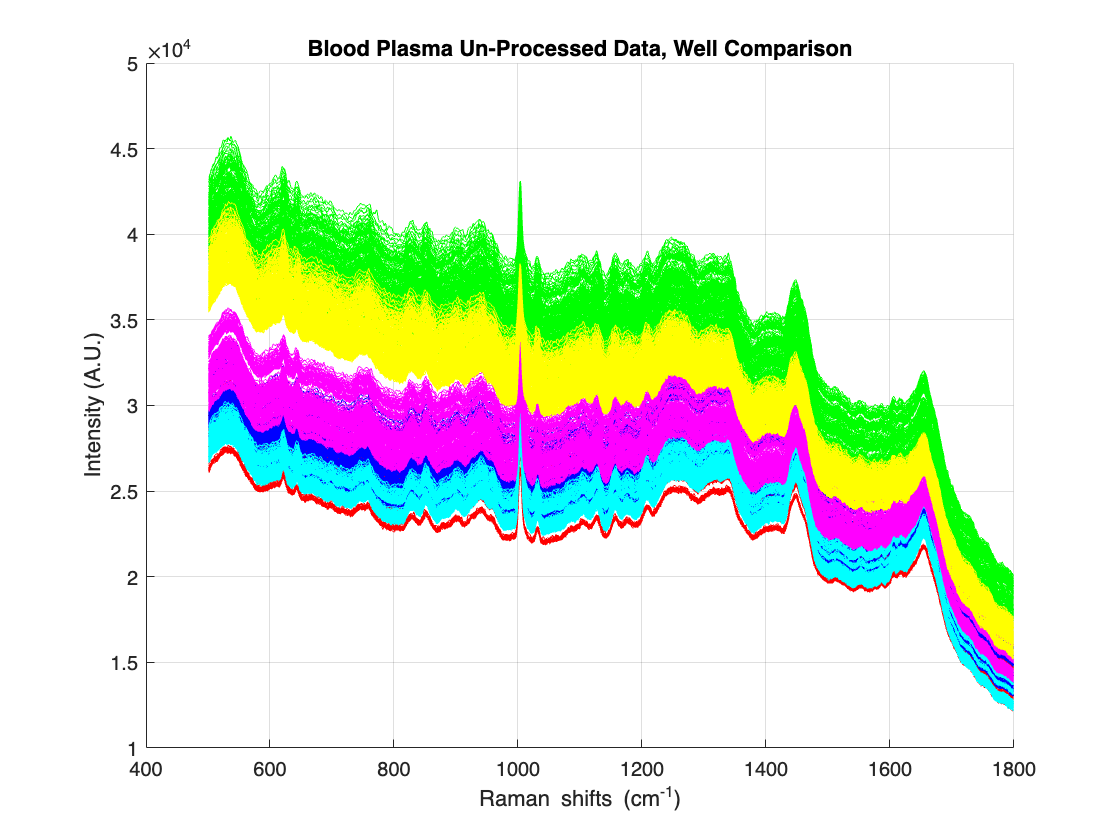

% Plotting Unprocessed Data

figure;
hold on;
grid on;
plot(wavenumber, blood1_1_3, '-r');
plot(wavenumber, blood2_1_3, '-r');
plot(wavenumber, blood3_1_3, '-r');
plot(wavenumber, blood4_1_3, '-r');
plot(wavenumber, blood5_1_3, '-r');
plot(wavenumber, blood6_1_3, '-r');
plot(wavenumber, blood7_1_3, '-r');
plot(wavenumber, blood8_1_3, '-r');
plot(wavenumber, blood9_1_3, '-r');
plot(wavenumber, blood10_1_3, '-r');
plot(wavenumber, blood1_2_3, '-b');
plot(wavenumber, blood2_2_3, '-b');
plot(wavenumber, blood3_2_3, '-b');
plot(wavenumber, blood4_2_3, '-b');
plot(wavenumber, blood5_2_3, '-b');
plot(wavenumber, blood6_2_3, '-b');
plot(wavenumber, blood7_2_3, '-b');
plot(wavenumber, blood8_2_3, '-b');
plot(wavenumber, blood9_2_3, '-b');
plot(wavenumber, blood10_2_3, '-b');
plot(wavenumber, blood1_3_3, '-g');
plot(wavenumber, blood2_3_3, '-g');
plot(wavenumber, blood3_3_3, '-g');
plot(wavenumber, blood4_3_3, '-g');
plot(wavenumber, blood5_3_3, '-g');
plot(wavenumber, blood6_3_3, '-g');
plot(wavenumber, blood7_3_3, '-g');
plot(wavenumber, blood8_3_3, '-g');
plot(wavenumber, blood9_3_3, '-g');
plot(wavenumber, blood10_3_3, '-g');
plot(wavenumber, blood1_1_4, '-c');
plot(wavenumber, blood2_1_4, '-c');
plot(wavenumber, blood3_1_4, '-c');
plot(wavenumber, blood4_1_4, '-c');
plot(wavenumber, blood5_1_4, '-c');
plot(wavenumber, blood6_1_4, '-c');
plot(wavenumber, blood7_1_4, '-c');
plot(wavenumber, blood8_1_4, '-c');
plot(wavenumber, blood9_1_4, '-c');
plot(wavenumber, blood10_1_4, '-c');
plot(wavenumber, blood1_2_4, '-m');
plot(wavenumber, blood2_2_4, '-m');
plot(wavenumber, blood3_2_4, '-m');
plot(wavenumber, blood4_2_4, '-m');
plot(wavenumber, blood5_2_4, '-m');
plot(wavenumber, blood6_2_4, '-m');
plot(wavenumber, blood7_2_4, '-m');
plot(wavenumber, blood8_2_4, '-m');
plot(wavenumber, blood9_2_4, '-m');
plot(wavenumber, blood10_2_4, '-m');
plot(wavenumber, blood1_3_4, '-y');
plot(wavenumber, blood2_3_4, '-y');
plot(wavenumber, blood3_3_4, '-y');
plot(wavenumber, blood4_3_4, '-y');
plot(wavenumber, blood5_3_4, '-y');
plot(wavenumber, blood6_3_4, '-y');
plot(wavenumber, blood7_3_4, '-y');
plot(wavenumber, blood8_3_4, '-y');
plot(wavenumber, blood9_3_4, '-y');
plot(wavenumber, blood10_3_4, '-y');
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Well Comparison');
hold off;

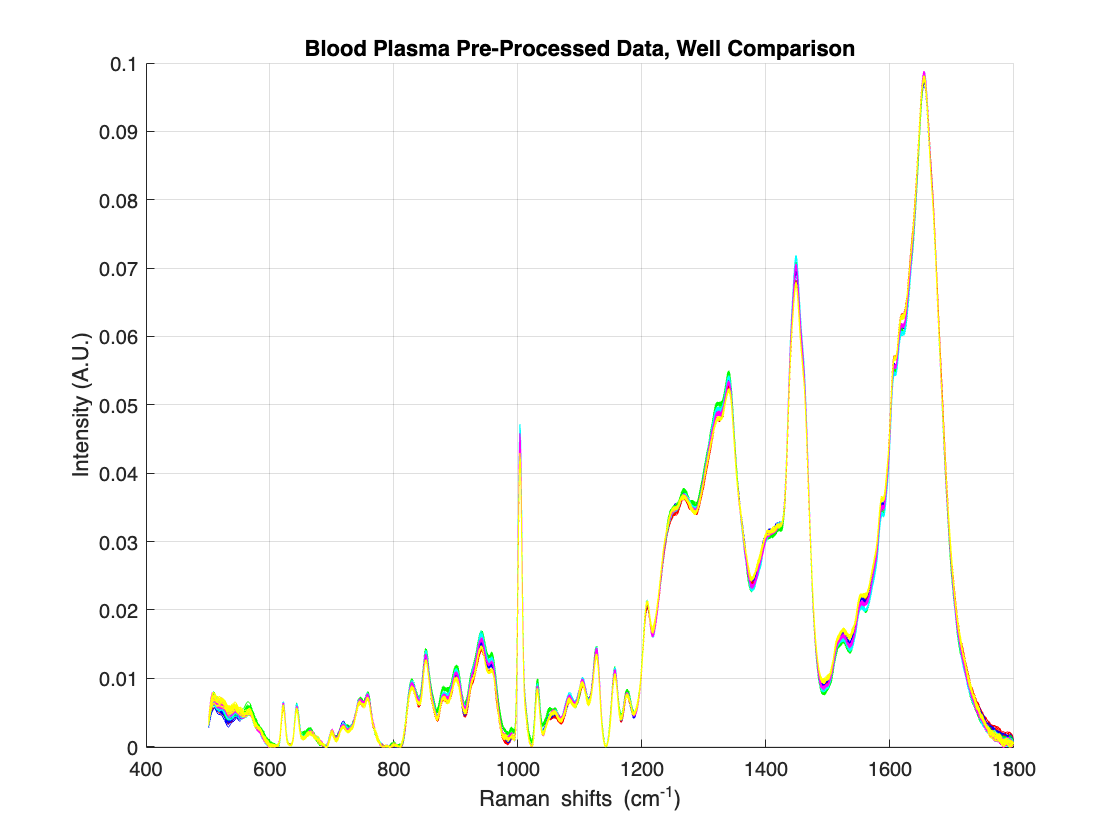

% Plotting Processed Data from Individual Wells

figure;
hold on;
grid on;
plot(corr_shifts, pro_blood_1_3, '-r');
plot(corr_shifts, pro_blood_2_3, '-b');
plot(corr_shifts, pro_blood_3_3, '-g');
plot(corr_shifts, pro_blood_1_4, '-c');
plot(corr_shifts, pro_blood_2_4, '-m');
plot(corr_shifts, pro_blood_3_4, '-y');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Well Comparison');
hold off;

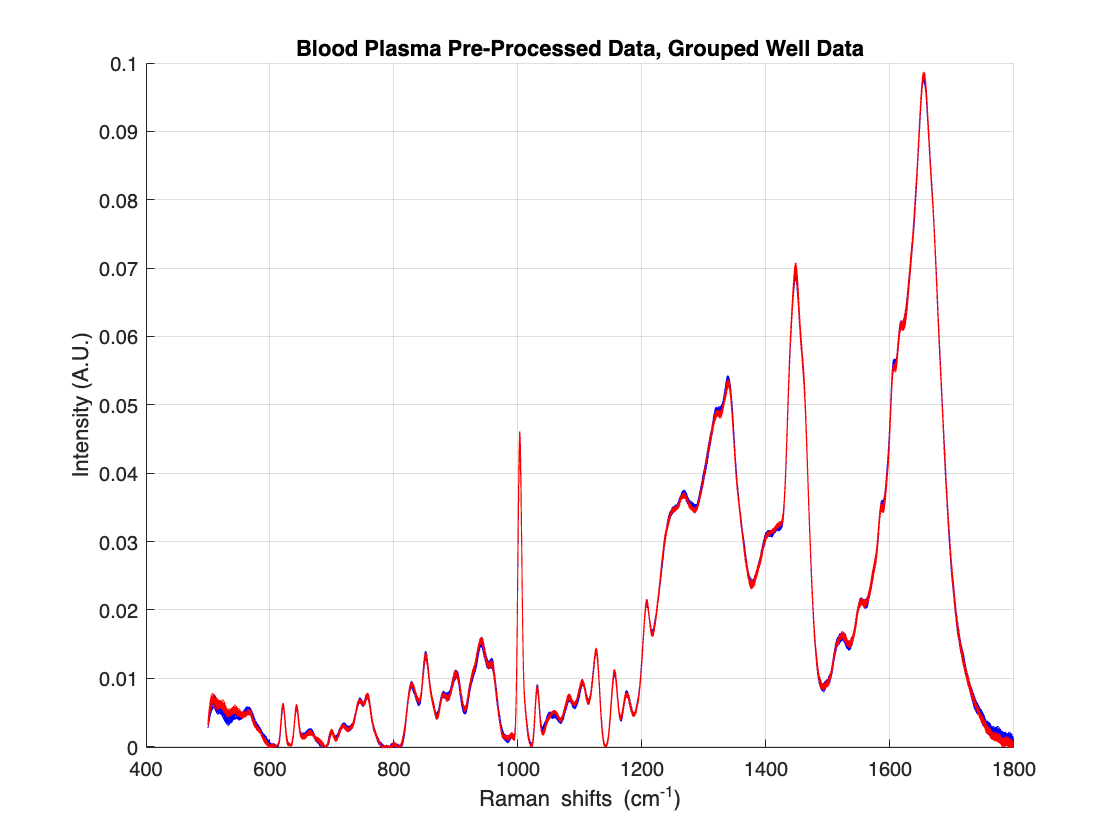

% Plotting Group Processed Data Day over Day

figure;
hold on;
grid on;
plot(corr_shifts, pro_blood_3, '-b');
plot(corr_shifts, pro_blood_4, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Grouped Well Data');
hold off;

% Data in 1003cm^{-1} peak
Trial1 = pro_blood_3(:, 503);
Trial2 = pro_blood_4(:, 503);

% Calculate means
av_Trial1 = mean(Trial1);
av_Trial2 = mean(Trial2);

% Calculate standard deviations
std_Trial1 = std(Trial1);
std_Trial2 = std(Trial2);

% Number of spectra in each trial
n_Trial1 = size(Trial1, 1);
n_Trial2 = size(Trial2, 1);

% Perform t-tests between pairs
[t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2] = perform_ttest(av_Trial1, av_Trial2, std_Trial1, std_Trial2, n_Trial1, n_Trial2);

% Display results
fprintf('t and p values for pairwise comparisons at 1003 cm^-1 peak:\n');

t and p values for pairwise comparisons at 1003 cm^-1 peak:


fprintf('Trial 1 vs Trial 2: t = %.4f, p = %.4f, df = %.4f\n', t_Trial1_Trial2, p_Trial1_Trial2, df_Trial1_Trial2);

Trial 1 vs Trial 2: t = -9.1010, p = 0.0000, df = 105.2419


## Removing Well 3

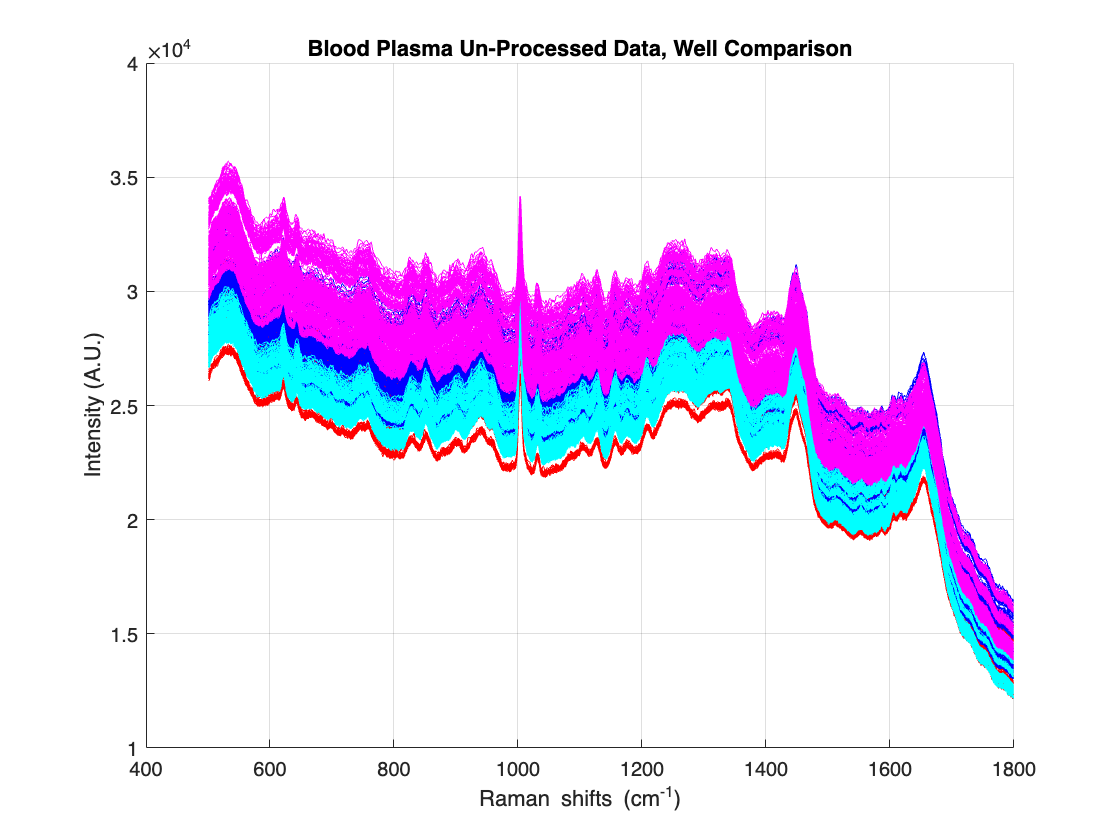

% Plotting Unprocessed Data

figure;
hold on;
grid on;
plot(wavenumber, blood1_1_3, '-r');
plot(wavenumber, blood2_1_3, '-r');
plot(wavenumber, blood3_1_3, '-r');
plot(wavenumber, blood4_1_3, '-r');
plot(wavenumber, blood5_1_3, '-r');
plot(wavenumber, blood6_1_3, '-r');
plot(wavenumber, blood7_1_3, '-r');
plot(wavenumber, blood8_1_3, '-r');
plot(wavenumber, blood9_1_3, '-r');
plot(wavenumber, blood10_1_3, '-r');
plot(wavenumber, blood1_2_3, '-b');
plot(wavenumber, blood2_2_3, '-b');
plot(wavenumber, blood3_2_3, '-b');
plot(wavenumber, blood4_2_3, '-b');
plot(wavenumber, blood5_2_3, '-b');
plot(wavenumber, blood6_2_3, '-b');
plot(wavenumber, blood7_2_3, '-b');
plot(wavenumber, blood8_2_3, '-b');
plot(wavenumber, blood9_2_3, '-b');
plot(wavenumber, blood10_2_3, '-b');
plot(wavenumber, blood1_1_4, '-c');
plot(wavenumber, blood2_1_4, '-c');
plot(wavenumber, blood3_1_4, '-c');
plot(wavenumber, blood4_1_4, '-c');
plot(wavenumber, blood5_1_4, '-c');
plot(wavenumber, blood6_1_4, '-c');
plot(wavenumber, blood7_1_4, '-c');
plot(wavenumber, blood8_1_4, '-c');
plot(wavenumber, blood9_1_4, '-c');
plot(wavenumber, blood10_1_4, '-c');
plot(wavenumber, blood1_2_4, '-m');
plot(wavenumber, blood2_2_4, '-m');
plot(wavenumber, blood3_2_4, '-m');
plot(wavenumber, blood4_2_4, '-m');
plot(wavenumber, blood5_2_4, '-m');
plot(wavenumber, blood6_2_4, '-m');
plot(wavenumber, blood7_2_4, '-m');
plot(wavenumber, blood8_2_4, '-m');
plot(wavenumber, blood9_2_4, '-m');
plot(wavenumber, blood10_2_4, '-m');
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Well Comparison');
hold off;

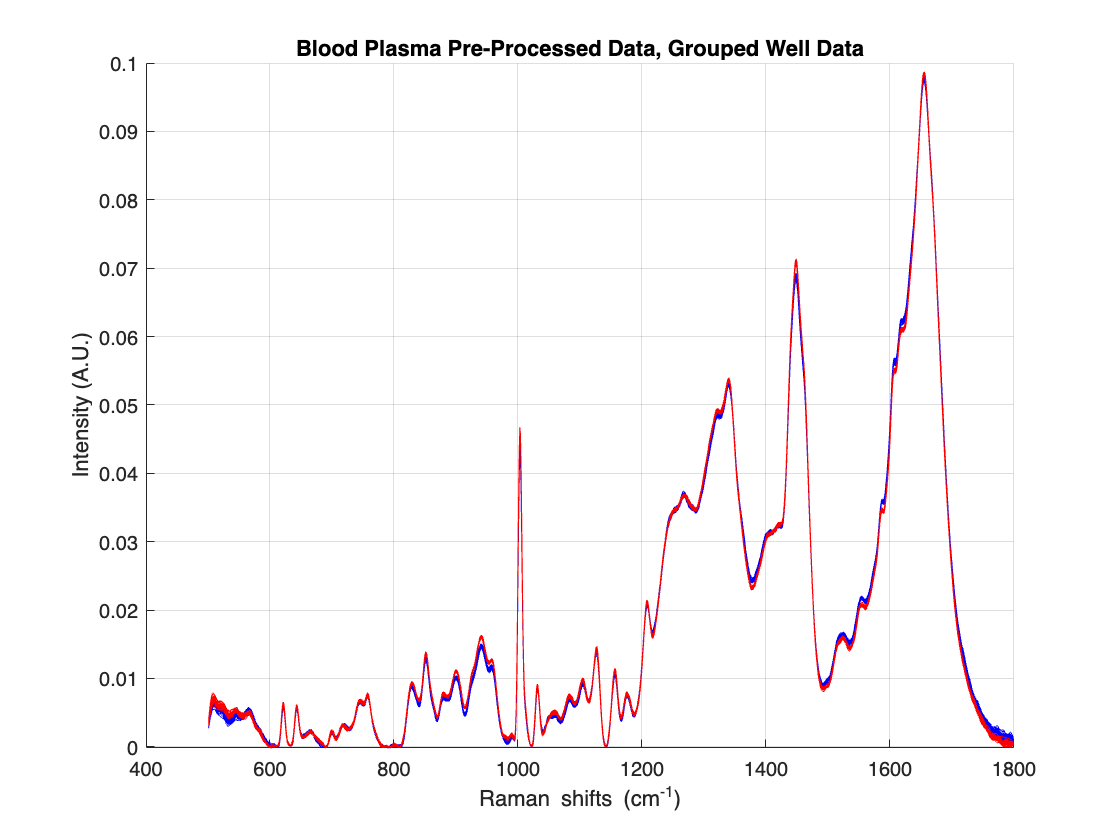

% Plotting Group Processed Data Day over Day

figure;
hold on;
grid on;
plot(corr_shifts, pro_blood_3_0, '-b');
plot(corr_shifts, pro_blood_4_0, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, Grouped Well Data');
hold off;

## Data from Day 1 and the Subplot

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-07-16/";


% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

file_name = "Blood_Plasma(40x,495mW,CG)_2500_24_2024-07-16-17.30.45.390.csv";
file_path = data_path+file_name;
blood_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,CG)_2500_24_2024-07-16-17.34.17.403.csv";
file_path = strcat(data_path,file_name);
blood_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,CG)_2500_24_2024-07-16-17.36.52.490.csv";
file_path = strcat(data_path,file_name);
blood_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,CG)_2500_24_2024-07-16-17.39.44.847.csv";
file_path = strcat(data_path,file_name);
blood_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,CG)_2500_24_2024-07-16-17.42.28.170.csv";
file_path = strcat(data_path,file_name);
blood_5 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,CG)_2500_24_2024-07-16-17.45.13.607.csv";
file_path = strcat(data_path,file_name);
blood_6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,CG)_2500_24_2024-07-16-17.47.59.203.csv";
file_path = strcat(data_path,file_name);
blood_7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,CG)_2500_24_2024-07-16-17.50.32.927.csv";
file_path = strcat(data_path,file_name);
blood_8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,CG)_2000_24_2024-07-16-17.53.48.730.csv";
file_path = strcat(data_path,file_name);
blood_9 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,CG)_2000_24_2024-07-16-17.55.52.113.csv";
file_path = strcat(data_path,file_name);
blood_10 = csvread(file_path, numMetadataRows, 0);

nist1 = readmatrix('Data/NIST_0823_120523_2023-05-12-08.23.54.csv');
NISTspectrum = [blood_6(1, 1:3101) ; nist1(23:end, :)];

file_name = "Polystyrene(40x,495mW)_70_100_2024-07-16-15.45.20.927.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_60_100_2024-07-16-15.41.03.040.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
blood_1(:, blood_1(1, :) <= t1) = [];
blood_1(:, blood_1(1, :) >= t2) = [];
blood_2(:, blood_2(1, :) <= t1) = [];
blood_2(:, blood_2(1, :) >= t2) = [];
blood_3(:, blood_3(1, :) <= t1) = [];
blood_3(:, blood_3(1, :) >= t2) = [];
blood_4(:, blood_4(1, :) <= t1) = [];
blood_4(:, blood_4(1, :) >= t2) = [];
blood_5(:, blood_5(1, :) <= t1) = [];
blood_5(:, blood_5(1, :) >= t2) = [];
blood_6(:, blood_6(1, :) <= t1) = [];
blood_6(:, blood_6(1, :) >= t2) = [];
blood_7(:, blood_7(1, :) <= t1) = [];
blood_7(:, blood_7(1, :) >= t2) = [];
blood_8(:, blood_8(1, :) <= t1) = [];
blood_8(:, blood_8(1, :) >= t2) = [];
blood_9(:, blood_9(1, :) <= t1) = [];
blood_9(:, blood_9(1, :) >= t2) = [];
blood_10(:, blood_10(1, :) <= t1) = [];
blood_10(:, blood_10(1, :) >= t2) = [];

shifts = wavenumber;

blood1 = blood_1(2:end, :);
blood2 = blood_2(2:end, :);
blood3 = blood_3(2:end, :);
blood4 = blood_4(2:end, :);
blood5 = blood_5(2:end, :);
blood6 = blood_6(2:end, :);
blood7 = blood_7(2:end, :);
blood8 = blood_8(2:end, :);
blood9 = blood_9(2:end, :);
blood10 = blood_10(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

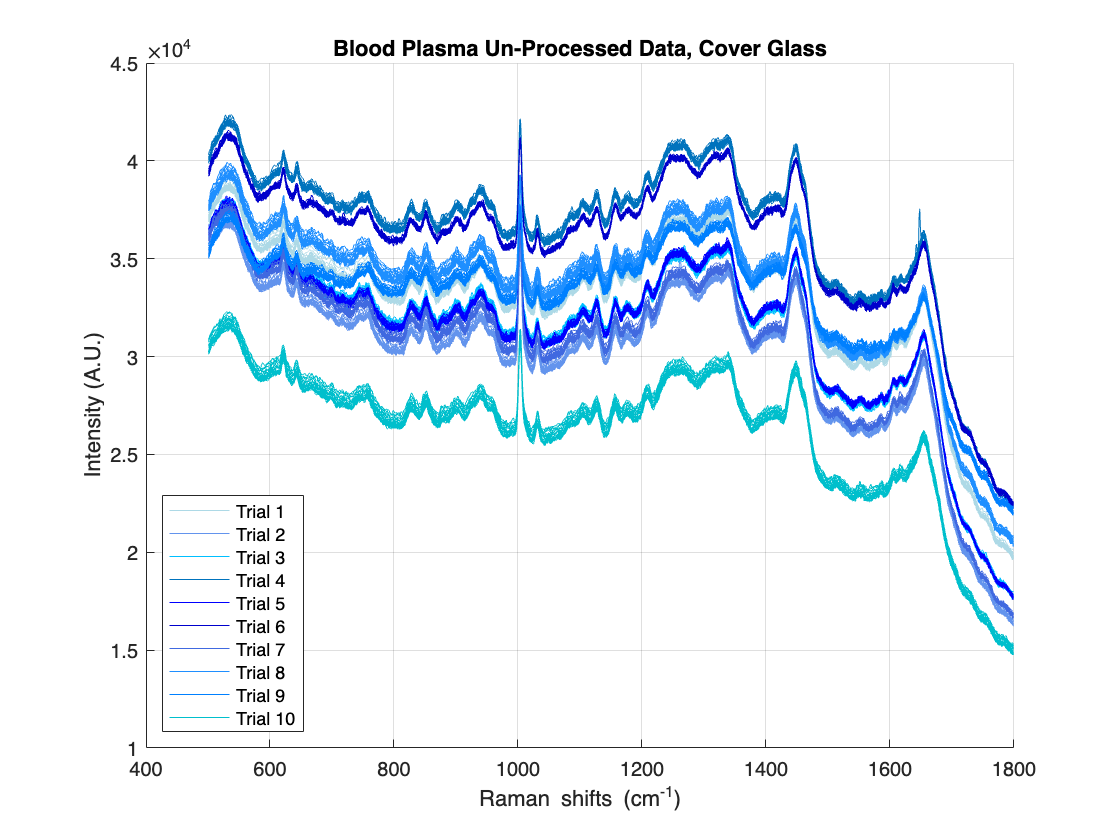

% Plotting unprocessed data

figure;
hold on;
grid on;

% Different shades of blue for the plots
plot(wavenumber, blood1(1,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(1,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3(1,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4(1,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(1,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(1,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(1,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, blood8(1,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(1,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(1,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

plot(wavenumber, blood1(2:end,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(2:end,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3(2:end,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4(2:end,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(2:end,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(2:end,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(2:end,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, blood8(2:end,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(2:end,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(2:end,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;

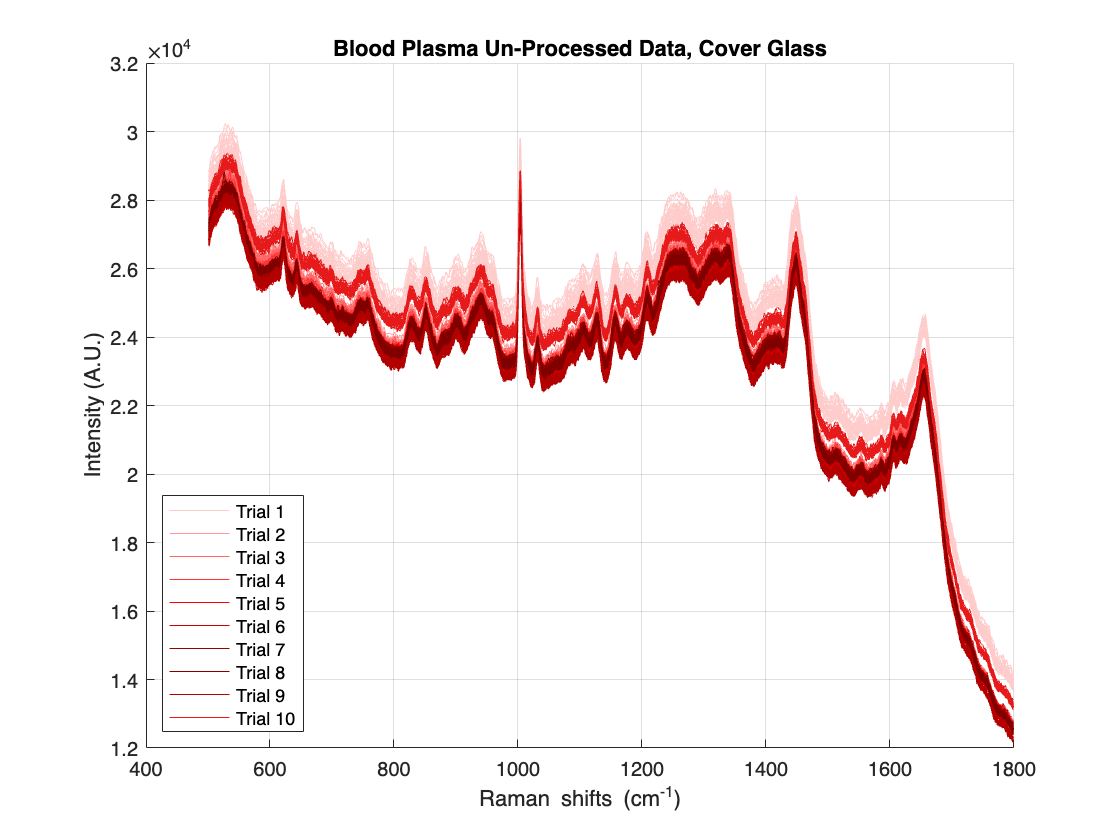


figure;
hold on;
grid on;
plot(wavenumber, blood1_1_4(1,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_1_4(1,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_1_4(1,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_1_4(1,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_1_4(1,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_1_4(1,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_1_4(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_1_4(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_1_4(1,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_1_4(1,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, blood1_1_4(2:end,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_1_4(2:end,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_1_4(2:end,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_1_4(2:end,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_1_4(2:end,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_1_4(2:end,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_1_4(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_1_4(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_1_4(2:end,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_1_4(2:end,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;

% Preprocessing the data

pro_blood1 = apply(blood1, [6,1,10,11,8,2,5,6,7]);
pro_blood2 = apply(blood2, [6,1,10,11,8,2,5,6,7]);
pro_blood3 = apply(blood3, [6,1,10,11,8,2,5,6,7]);
pro_blood4 = apply(blood4, [6,1,10,11,8,2,5,6,7]);
pro_blood5 = apply(blood5, [6,1,10,11,8,2,5,6,7]);
pro_blood6 = apply(blood6, [6,1,10,11,8,2,5,6,7]);
pro_blood7 = apply(blood7, [6,1,10,11,8,2,5,6,7]);
pro_blood8 = apply(blood8, [6,1,10,11,8,2,5,6,7]);
pro_blood9 = apply(blood9, [6,1,10,11,8,2,5,6,7]);
pro_blood10 = apply(blood10, [6,1,10,11,8,2,5,6,7]);

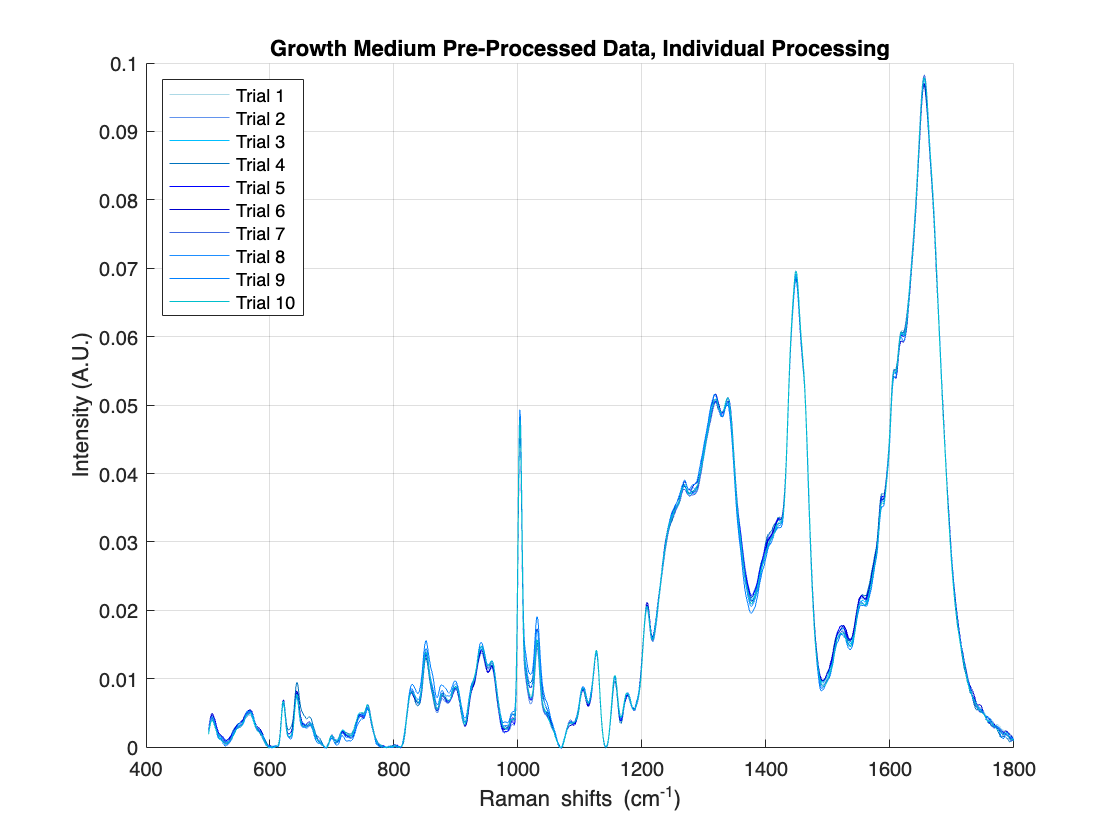

% Different shades of blue for the plots
figure;
hold on;
grid on;

plot(wavenumber, pro_blood1, 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, pro_blood2, 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, pro_blood3, 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, pro_blood4, 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, pro_blood5, 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, pro_blood6, 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, pro_blood7, 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, pro_blood8, 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, pro_blood9, 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, pro_blood10, 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Growth Medium Pre-Processed Data, Individual Processing');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
hold off;

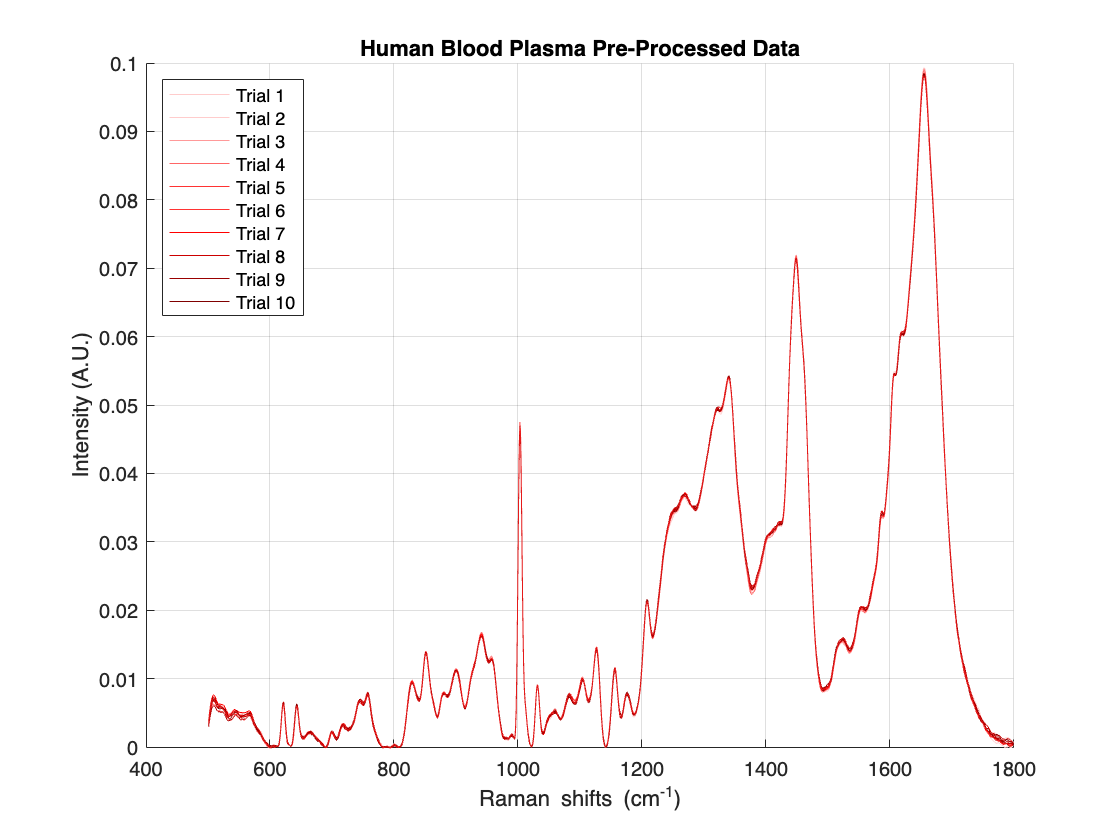

figure;
hold on;
grid on;
plot(wavenumber, pro_blood1_1, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, pro_blood2_1, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, pro_blood3_1, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, pro_blood4_1, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, pro_blood5_1, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, pro_blood6_1, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, pro_blood7_1, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood8_1, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, pro_blood9_1, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, pro_blood10_1, 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Human Blood Plasma Pre-Processed Data');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
hold off;

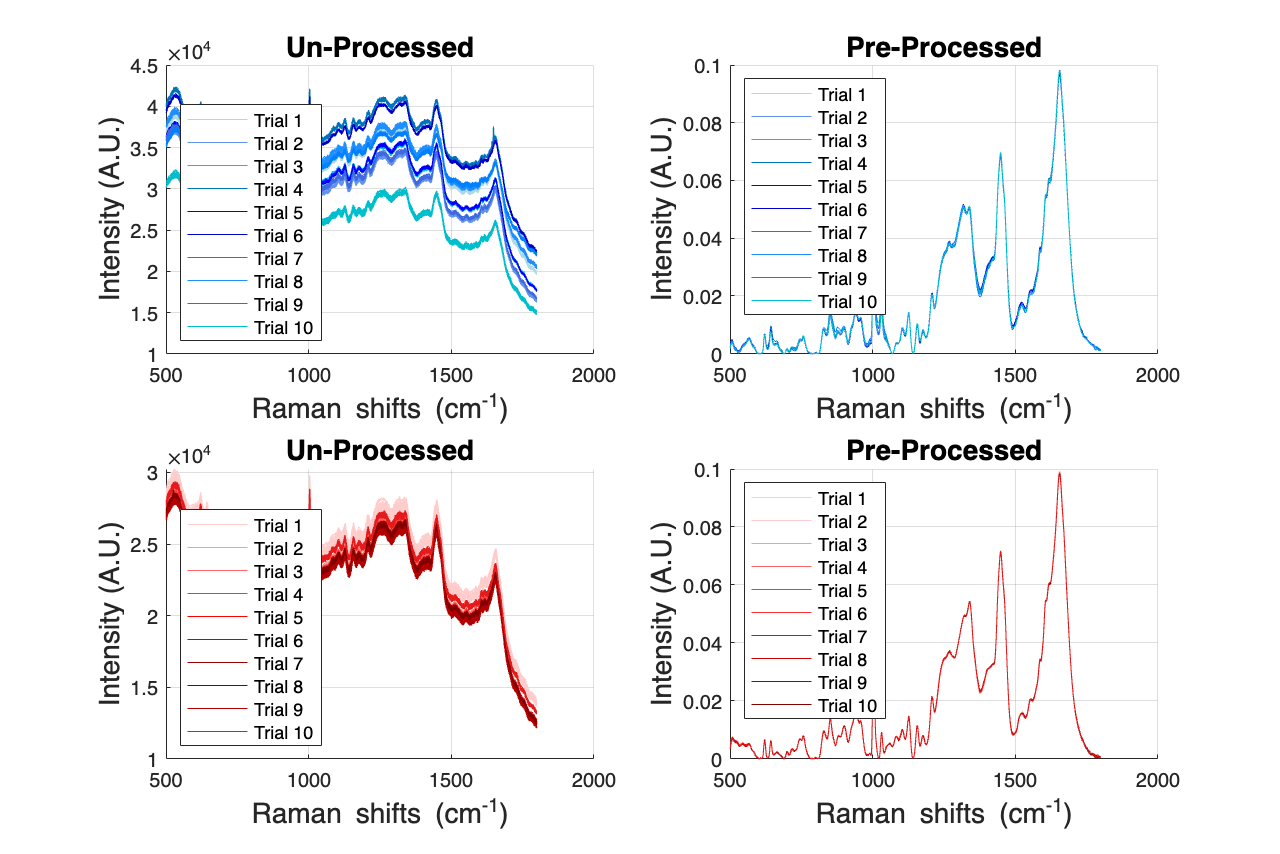

fig = figure('Position', [100, 100, 1200, 800]);

% Top left subplot
subplot(2, 2, 1); % 2 rows, 2 columns, first subplot
hold on;
grid on;
% Different shades of blue for the plots
plot(wavenumber, blood1(1,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(1,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3(1,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4(1,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(1,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(1,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(1,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, blood8(1,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(1,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(1,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise
plot(wavenumber, blood1(2:end,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(2:end,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3(2:end,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4(2:end,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(2:end,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(2:end,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(2:end,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, blood8(2:end,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(2:end,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(2:end,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise
xlabel('Raman shifts (cm^{-1})', 'FontSize', 14);
ylabel('Intensity (A.U.)', 'FontSize', 14);
title('Un-Processed', 'FontSize', 14);
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest', 'FontSize', 9);
hold off;

% Top right subplot
subplot(2, 2, 2); % 2 rows, 2 columns, second subplot
hold on;
grid on;
% Different shades of blue for the plots
plot(wavenumber, pro_blood1, 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, pro_blood2, 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, pro_blood3, 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, pro_blood4, 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, pro_blood5, 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, pro_blood6, 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, pro_blood7, 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, pro_blood8, 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, pro_blood9, 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, pro_blood10, 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise
xlabel('Raman shifts (cm^{-1})', 'FontSize', 14);
ylabel('Intensity (A.U.)', 'FontSize', 14);
title('Pre-Processed', 'FontSize', 14);
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest', 'FontSize', 9);
hold off;

% Bottom left subplot
subplot(2, 2, 3); % 2 rows, 2 columns, third subplot
hold on;
grid on;
% Different shades of red for the plots
plot(wavenumber, blood1_1_4(1,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_1_4(1,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_1_4(1,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_1_4(1,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_1_4(1,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_1_4(1,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_1_4(1,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_1_4(1,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_1_4(1,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_1_4(1,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
plot(wavenumber, blood1_1_4(2:end,:), 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, blood2_1_4(2:end,:), 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, blood3_1_4(2:end,:), 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, blood4_1_4(2:end,:), 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, blood5_1_4(2:end,:), 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, blood6_1_4(2:end,:), 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, blood7_1_4(2:end,:), 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, blood8_1_4(2:end,:), 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, blood9_1_4(2:end,:), 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, blood10_1_4(2:end,:), 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})', 'FontSize', 14);
ylabel('Intensity (A.U.)', 'FontSize', 14);
title('Un-Processed', 'FontSize', 14);
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest', 'FontSize', 9);
hold off;

% Bottom right subplot
subplot(2, 2, 4); % 2 rows, 2 columns, fourth subplot
hold on;
grid on;
% Different shades of red for the plots
plot(wavenumber, pro_blood1_1, 'Color', [1.00, 0.80, 0.80]); % Light Red
plot(wavenumber, pro_blood2_1, 'Color', [1.00, 0.60, 0.60]); % Light Coral
plot(wavenumber, pro_blood3_1, 'Color', [1.00, 0.40, 0.40]); % Salmon
plot(wavenumber, pro_blood4_1, 'Color', [1.00, 0.20, 0.20]); % Indian Red
plot(wavenumber, pro_blood5_1, 'Color', [1.00, 0.00, 0.00]); % Red
plot(wavenumber, pro_blood6_1, 'Color', [0.80, 0.00, 0.00]); % Fire Brick
plot(wavenumber, pro_blood7_1, 'Color', [0.60, 0.00, 0.00]); % Dark Red
plot(wavenumber, pro_blood8_1, 'Color', [0.50, 0.00, 0.00]); % Maroon
plot(wavenumber, pro_blood9_1, 'Color', [0.70, 0.00, 0.00]); % Crimson
plot(wavenumber, pro_blood10_1, 'Color', [0.90, 0.10, 0.10]); % Light Red
xlabel('Raman shifts (cm^{-1})', 'FontSize', 14);
ylabel('Intensity (A.U.)', 'FontSize', 14);
title('Pre-Processed', 'FontSize', 14);
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest', 'FontSize', 9);
hold off;
% Save the current figure as a high-resolution JPEG
print('Blood_Plasma_Repeatability','-djpeg','-r600');

function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = (av1 - av2) / sqrt((std1^2 / n1) + (std2^2 / n2));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end